## **PROBLEM 1**

The equivalent homogenous transformation for these set of rotations is given by,

R = R1*R2*R3

where R1 = $\left\lbrack \begin{array}{cccc}
\cos {\left(45\right)}^o  & -\sin {\left(45\right)}^o  & 0 & 0\\
\sin {\left(45\right)}^o  & \cos {\left(45\right)}^o  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

R2 = $\left\lbrack \begin{array}{cccc}
\cos {\left(30\right)}^o  & 0 & \sin {\left(30\right)}^o  & 0\\
0 & 1 & 0 & 0\\
-\sin {\left(30\right)}^o  & 0 & \cos {\left(30\right)}^o  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

R3 = $\left\lbrack \begin{array}{cccc}
\cos {\left(20\right)}^o  & -\sin {\left(20\right)}^o  & 0 & 0\\
\sin {\left(20\right)}^o  & \cos {\left(20\right)}^o  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

clear all

R1 = [[cosd(45) -sind(45) 0 0];
      [sind(45) cosd(45) 0 0];
      [0 0 1 0];
      [0 0 0 1]];
R2 = [[cosd(30) 0 sind(30) 0];
      [0 1 0 0];
      [-sind(30) 0 cosd(30) 0];
      [0 0 0 1]];
R3 = [[cosd(20) -sind(20) 0 0];
      [sind(20) cosd(20) 0 0];
      [0 0 1 0];
      [0 0 0 1]];
R = R1*R2*R3;

R = $\left\lbrack \begin{array}{cccc}
0\ldotp 3336 & -0\ldotp 8379 & 0\ldotp 3536 & 0\\
0\ldotp 8173 & 0\ldotp 4550 & 0\ldotp 3536 & 0\\
-0\ldotp 4698 & 0\ldotp 1710 & 0\ldotp 8660 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

**(A)** Since this is a case of pure rotation, let's consider only the rotation matrix,

r10 = [[0.3336 -0.8379 0.3536];
     [0.8173 0.4550 0.3536];
     [-0.4698 0.1710 0.8660]];
r0 = [[1 0 0];
      [0 1 0];
      [0 0 1]];

% time steps are from t=0 to t=10, in steps of 2
t = (2:2:8)';
r_int = zeros(3,3,4);
% interpolating each element of the matrix linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0,1))
        for k = (1:1:size(r0,2))
            r_int(j,k,i) = (((r10(j,k)-r0(j,k))/(10))*T)+r0(j,k);            
        end
    end
end
r2 = r_int(:,:,1); % intermediate rotation matrix at t=2s
r4 = r_int(:,:,2); % intermediate rotation matrix at t=4s
r6 = r_int(:,:,3); % intermediate rotation matrix at t=6s
r8 = r_int(:,:,4); % intermediate rotation matrix at t=8s

figure;
view([170 35])
trplot(r0,'color','r');
hold on
trplot(r2,'color','g');

hold on
trplot(r4,'color','b');

hold on
trplot(r6,'color','m');

hold on
trplot(r8,'color','c');

hold on
trplot(r10,'color','k');

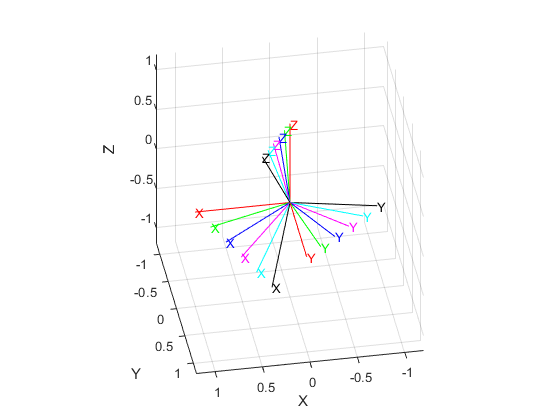

hold off

B) The absolute XYZ Euler angles can be obtained from the rotation matrix by considering the  sequence of rotations as Z-Y-X,

For the given rotation matrix, we get two sets of Euler angles,


$$\begin{array}{l}
{\theta \;}_1 {\;=28\ldotp 02\deg \;\;\psi }_1 =11\ldotp 17\deg \;\;\phi_1 =67\ldotp 8\deg \\
{\theta \;}_2 {\;=\;151\ldotp 98\deg \;\;\psi }_2 =191\ldotp 17\deg \;\;\phi_2 =247\ldotp 8\deg 
\end{array}$$


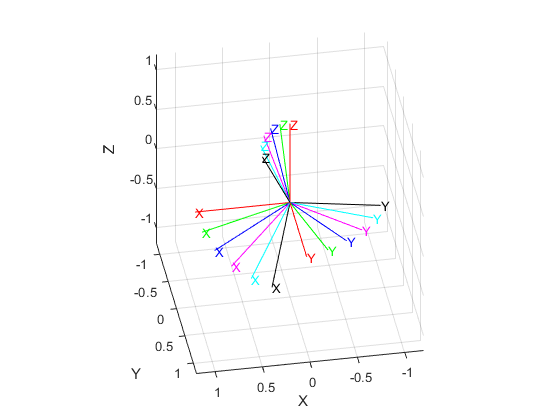

%linear interpolation between the angles
% time steps are from t=0 to t=10, in steps of 2
r_eul_int = zeros(1,3,4);
r0_eul = [0 0 0];
r10_eul = [28.02 11.17 67.8];

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_eul,1))
        for k = (1:1:size(r0_eul,2))
            r_eul_int(j,k,i) = (((r10_eul(j,k)-r0_eul(j,k))/(10))*T)+r0_eul(j,k);            
        end
    end
end
r2_eul = r_eul_int(:,:,1);
r4_eul = r_eul_int(:,:,2);
r6_eul = r_eul_int(:,:,3);
r8_eul = r_eul_int(:,:,4);

% finding the corresponding rotation matrix using these angles

syms phi theta psi real

Rzphi   = [[cosd(phi) -sind(phi) 0];
           [sind(phi) cosd(phi) 0];
           [0 0 1]];
Rytheta = [[cosd(theta) 0 sind(theta)];
           [0 1 0];
           [-sind(theta) 0 cosd(theta)]];
Rxpsi   = [[1 0 0];
           [0 cosd(psi) -sind(psi)];
           [0 sind(psi) cosd(psi)]];
Rzyx    = Rzphi*Rytheta*Rxpsi;

r0_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r0_eul(1,1),r0_eul(1,2),r0_eul(1,3)}));
r2_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r2_eul(1,1),r2_eul(1,2),r2_eul(1,3)}));
r4_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r4_eul(1,1),r4_eul(1,2),r4_eul(1,3)}));
r6_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r6_eul(1,1),r6_eul(1,2),r6_eul(1,3)}));
r8_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r8_eul(1,1),r8_eul(1,2),r8_eul(1,3)}));
r10_eul2rotm= double(subs(Rzyx,{theta,psi,phi},{r10_eul(1,1),r10_eul(1,2),r10_eul(1,3)}));

figure;
view([170 35])
trplot(r0_eul2rotm,'color','r');
hold on
trplot(r2_eul2rotm,'color','g');
hold on
trplot(r4_eul2rotm,'color','b');
hold on
trplot(r6_eul2rotm,'color','m');
hold on
trplot(r8_eul2rotm,'color','c');
hold on
trplot(r10_eul2rotm,'color','k');
hold off

**Since the other set of angles also yield the same rotation matrix, the intermediate euler angles would also render the same rotation matrices.**

C) The relative XYZ Euler angles can be obtained from the rotation matrix by considering the  sequence of rotations as X-Y-Z,

For the given rotation matrix, the Euler angles obtained are,

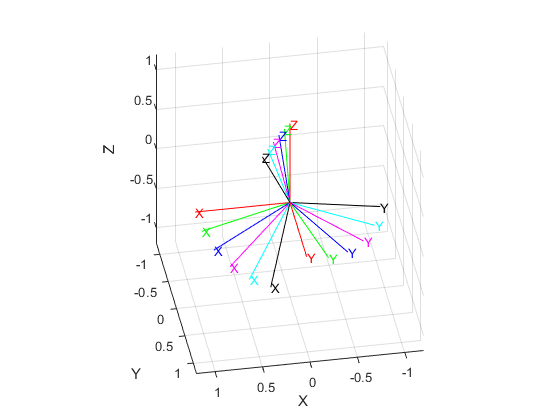

% finding the XYZ Euler angles corresponding to the two rotation matrices
r0_xyz = rotm2eul(r0,'XYZ');
r10_xyz = rotm2eul(r10,'XYZ');
r_xyz_int = zeros(1,3,4);

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_xyz,1))
        for k = (1:1:size(r0_xyz,2))
            r_xyz_int(j,k,i) = (((r10_xyz(j,k)-r0_xyz(j,k))/(10))*T)+r0_xyz(j,k);            
        end
    end
end

r2_xyz = r_xyz_int(:,:,1);
r4_xyz = r_xyz_int(:,:,2);
r6_xyz = r_xyz_int(:,:,3);
r8_xyz = r_xyz_int(:,:,4);

% finding the corresponding rotation matrix using these angles
syms phi theta psi real

Rxphi   = [[1 0 0];[0 cos(phi) -sin(phi)];[0 sin(phi) cos(phi)]];
Rytheta = [[cos(theta) 0 sin(theta)];[0 1 0];[-sin(theta) 0 cos(theta)]];
Rzpsi   = [[cos(psi) -sin(psi) 0];[sin(psi) cos(psi) 0];[0 0 1]];
Rxyz    = Rxphi*Rytheta*Rzpsi;

r0_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r0_xyz(1,1),r0_xyz(1,2),r0_xyz(1,3)}));
r2_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r2_xyz(1,1),r2_xyz(1,2),r2_xyz(1,3)}));
r4_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r4_xyz(1,1),r4_xyz(1,2),r4_xyz(1,3)}));
r6_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r6_xyz(1,1),r6_xyz(1,2),r6_xyz(1,3)}));
r8_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r8_xyz(1,1),r8_xyz(1,2),r8_xyz(1,3)}));
r10_xyz2rotm= double(subs(Rxyz,{phi,theta,psi},{r10_xyz(1,1),r10_xyz(1,2),r10_xyz(1,3)}));

figure;
view([170 35])
trplot(r0_xyz2rotm,'color','r');
hold on
trplot(r2_xyz2rotm,'color','g');
hold on
trplot(r4_xyz2rotm,'color','b');
hold on
trplot(r6_xyz2rotm,'color','m');
hold on
trplot(r8_xyz2rotm,'color','c');
hold on
trplot(r10_xyz2rotm,'color','k');
hold off

D) Axis angle representation can be found out using the function 'rotm2axang'

r0_axang = rotm2axang(r0);
r10_axang = rotm2axang(r10);
r_axang_int = zeros(1,4,4);

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_axang,1))
        for k = (1:1:size(r0_axang,2))
            r_axang_int(j,k,i) = (((r10_axang(j,k)-r0_axang(j,k))/(10))*T)+r0_axang(j,k);            
        end
    end
end

r2_axang = r_axang_int(:,:,1);
r4_axang = r_axang_int(:,:,2);
r6_axang = r_axang_int(:,:,3);
r8_axang = r_axang_int(:,:,4);

%finding the corresponding rotation matrix using these axis and angles

syms kx ky kz theta real

Raxang = [[kx^2*(1-cos(theta))+cos(theta) kx*ky*(1-cos(theta))-kz*sin(theta) kx*kz*(1-cos(theta))+ky*sin(theta)];
          [kx*ky*(1-cos(theta))+kz*sin(theta) ky^2*(1-cos(theta))+cos(theta) ky*kz*(1-cos(theta))-kx*sin(theta)];
          [kx*kz*(1-cos(theta))-ky*sin(theta) ky*kz*(1-cos(theta))+kx*sin(theta) kz^2*(1-cos(theta))+cos(theta)]];

r0_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r0_axang(1,1),r0_axang(1,2),r0_axang(1,3),r0_axang(1,4)}));
r2_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r2_axang(1,1),r2_axang(1,2),r2_axang(1,3),r2_axang(1,4)}));
r4_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r4_axang(1,1),r4_axang(1,2),r4_axang(1,3),r4_axang(1,4)}));
r6_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r6_axang(1,1),r6_axang(1,2),r6_axang(1,3),r6_axang(1,4)}));
r8_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r8_axang(1,1),r8_axang(1,2),r8_axang(1,3),r8_axang(1,4)}));
r10_axang2rotm= double(subs(Raxang,{kx,ky,kz,theta},{r10_axang(1,1),r10_axang(1,2),r10_axang(1,3),r10_axang(1,4)}));

figure;
view([170 35])
trplot(r0_axang2rotm,'color','r');
hold on
trplot(r2_axang2rotm,'color','g');

hold on
trplot(r4_axang2rotm,'color','b');

hold on
trplot(r6_axang2rotm,'color','m');

hold on
trplot(r8_axang2rotm,'color','c');

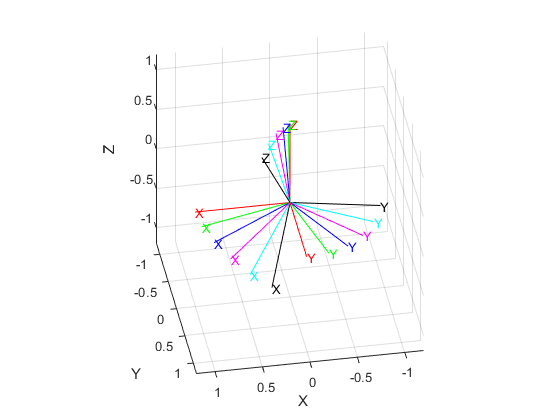

hold on
trplot(r10_axang2rotm,'color','k');
hold off

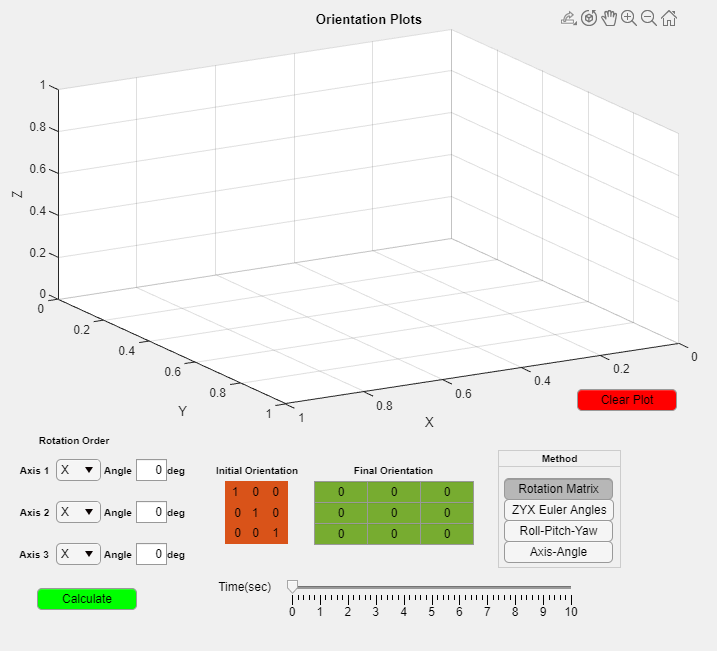

run('Q1_GUI.mlapp');

**Inputs to the GUI are as follows,**

(1) Axis of rotation for the frames

(2) Corresponding angles of rotation

(3) Method of interpolation

(4) Time in seconds, at which the position of the frame needs to be visualised

**Directions to use the GUI,**

(1) Enter the axis and angles of rotation, press calculate. This calculates the 'Final Orientation' matrix

     The initial orientation matrix is assumed to be aligned with the global frame of reference

(2) Select the method of interpolations, which essentially decides what will be interpolated

(3) Slide the 'time' slider to visualise the frames at different times

(4) Press clear plot to clear the figure, to be used when switching from one method to the other

## **PROBLEM 2**